## FUNCTIONAL DATA ANALYSIS

load AlturaChicas.mat
load EdadChicas.mat
load AlturaChicos.mat

The height and age data is stored in variables called  "hgtffit" y "age" respectively. Let's start by representing the data for a single girl. 

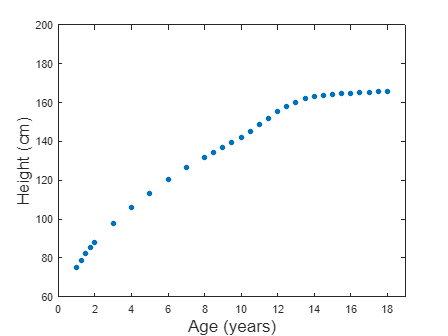

figure();
girl = 27;
plot(age, hgtffit(:, girl), '.', 'MarkerSize', 15); 
xlabel('Age (years)', 'FontSize', 16); 
ylabel('Height (cm)', 'FontSize', 16); 
xlim([0, 19]);
ylim([60, 200]);

We can repeat the process to show the information about all the girls in the data set. 

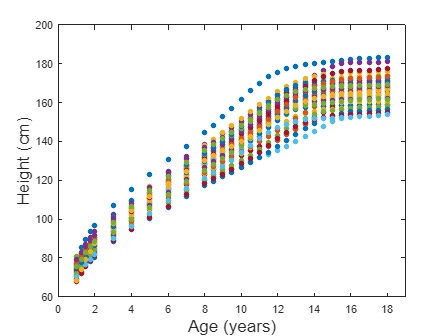

figure();
for girl = 1:54
    individual_heights = hgtffit(:,girl);
    plot(age, individual_heights, '.', 'MarkerSize', 15); % Representation of the data
    hold on; 
end
xlabel('Age (years)', 'FontSize', 16); 
ylabel('Height (cm)', 'FontSize', 16); 
xlim([0, 19]);
ylim([60, 200]);
hold off

As we can see, the discrete data help us to visualise the evolution of height throughout the girls' lives. However, it would be helpful to be able to estimate the intermediate values, i.e. those between the actual measured values. For this purpose, the best option would be to approximate functions that define this evolution for each of the girls. We will now look at 3 possible options:

### 1. GRADE 1 LINEAR SMOOTHING

To make it simpler, we will initially work with the data of a girl. 

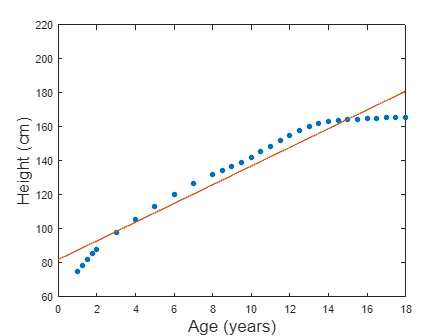

ages = age; 
heights = hgtffit(:,27); % I have chosen girl 27

% The polyfit function is used to adjust the straight line (degree 1) to the data of our subject.
coefficients = polyfit(ages, heights, 1); % 

m = coefficients(1); % Slope
b = coefficients(2); % Intersection

% Creating a linear function
funcion_lineal = @(x) m * x + b;


% Once we have created the linear function for our initial data we can try to get more discrete data by doing an age interpolation. 
% To do this:
interp_ages = 0:0.1:18;

% Calculate smoothed heights (substitute ages in the function)
interp_heights = funcion_lineal(interp_ages);

figure();
plot(ages, heights, '.', 'MarkerSize', 15);
hold on; 
plot(interp_ages, interp_heights, '-');
hold off;  

xlabel('Age (years)');
ylabel('Height (cm)');

xlabel('Age (years)', 'FontSize', 16); 
ylabel('Height (cm)', 'FontSize', 16); 

ylim([60, 220]);

To calculate the error, the easiest way is to use the mean absolute error. We can also calculate as an extra parameter the MAD.

% Calculate predicted heights with linear adjustment
predicted_heights = funcion_lineal(age);
% Calculate MAE and MAD
mae = mean(abs(heights - predicted_heights));
mad = median(abs(heights - predicted_heights));

disp(['Mean Absolute Error of a girl(MAE): ', num2str(mae)]);

Mean Absolute Error of a girl(MAE): 6.1931


disp(['Median Absolute Deviation of a girl(MAD): ', num2str(mad)]);

Median Absolute Deviation of a girl(MAD): 5.6854


We can repeat the process for all the data set.

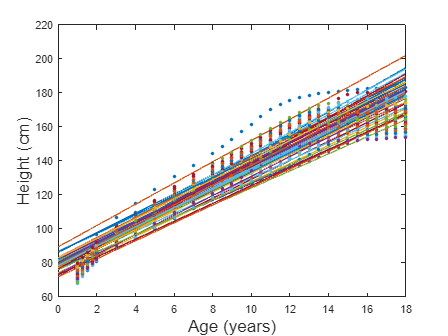

figure();
mae = zeros(1, 54); % We create 2 zero vectors to store the values for MAE and MAD
mad = zeros(1, 54); 
mae_2 = zeros(31,54);

for girl = 1:54
    ages = age;
    heights = hgtffit(:,girl); 
    coefficients = polyfit(ages, heights, 1); 
    m = coefficients(1); % Slope
    b = coefficients(2); % Intersection
    funcion_lineal = @(x) m * x + b;
    interp_ages = 0:0.1:18;
    interp_heights = funcion_lineal(interp_ages);
    plot(ages, heights, '.', 'MarkerSize', 10);
    hold on; 
    plot(interp_ages, interp_heights, '-');

    
    xlabel('Age (years)', 'FontSize', 16); 
    ylabel('Height (cm)', 'FontSize', 16); 

    ylim([60, 220]);
    
    hold on
    
    predicted_heights = funcion_lineal(age);
    difference = abs(heights - predicted_heights);
    mae(girl) = mean(difference);
    mad(girl) = median(difference); 
    
    mae_2(:,girl) = difference;



end
hold off

mae_final = mean (mae);
disp(['Mean Absolute Error of all the girls (MAE): using degree 1 linear smoothing: ', num2str(mae_final), ' cm']);

Mean Absolute Error of all the girls (MAE): using degree 1 linear smoothing: 5.6092 cm



mad_final = mean (mad);
disp(['Median Absolute Deviation of all the girls (MAE): using degree 1 linear smoothing:  ', num2str(mad_final), ' cm']);

Median Absolute Deviation of all the girls (MAE): using degree 1 linear smoothing:  5.0169 cm


We average the MAE values for each time instant and plot, thus obtaining the MAE evolution.

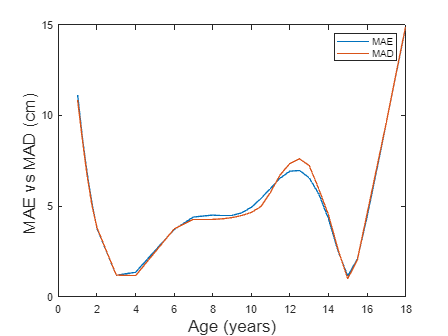

mae_final = mean(mae_2, 2);
mad_final = median(mae_2, 2);
figure
plot (age, mae_final, 'MarkerSize', 20 );
hold on
plot (age, mad_final, 'MarkerSize', 20 );
xlabel('Age (years)','FontSize', 16);

ylabel('MAE vs MAD (cm) ','FontSize', 16);
legend('MAE', 'MAD');

hold off

### 2. BERTALANFFY MODEL

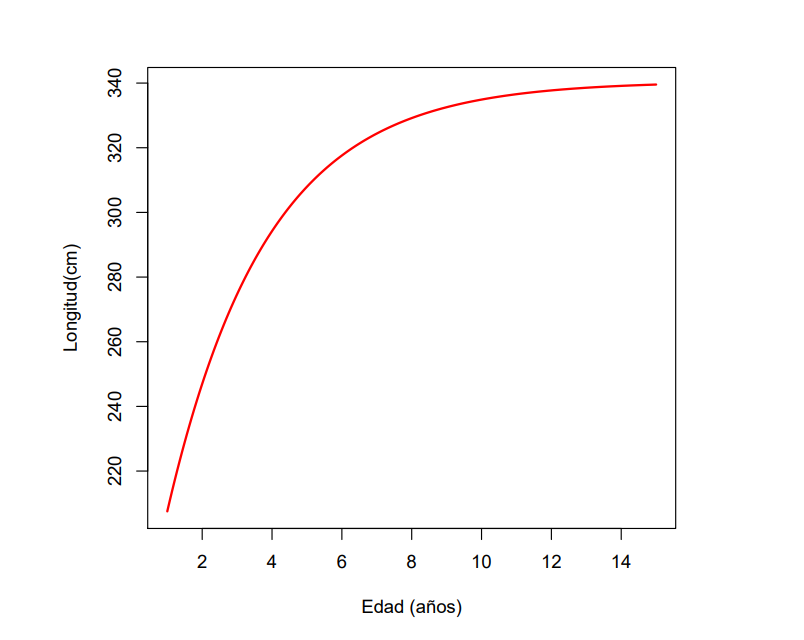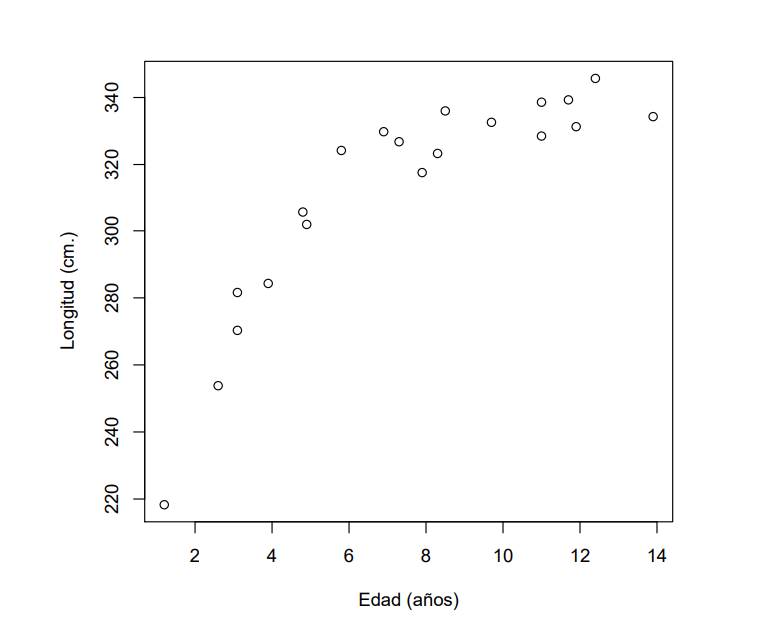

We start with a single girl.

load('AlturaChicas.mat')
load('EdadChicas.mat')

height = hgtffit(:,27);

% Define the Bertalanffy function used
bertalanffy = @(p, t) p(1) * (1 - exp(-p(2) * (t - p(3))));

initial_value = max(height);

% We suppose these initial parameters
initial_values = [initial_value, 0.03, 0];

    
% We adjust the model to our data set, obtaining for each subject specific
% parameters
adjusted_parameters = lsqcurvefit(bertalanffy, initial_values, age, height);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


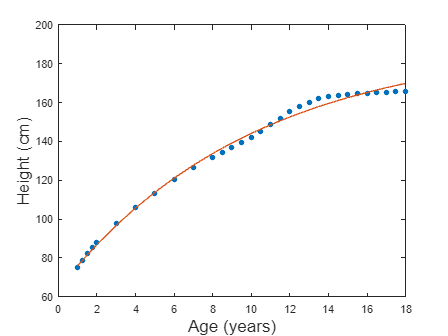


% Obtain the adjusted parameters
L_infty = adjusted_parameters(1);
k = adjusted_parameters(2);
t_0 = adjusted_parameters(3);

% Obtain the predicted values and represent them
adjusted_model = bertalanffy(adjusted_parameters, age);

figure
plot(age, height, '.', 'MarkerSize', 15)
hold on
plot(age, adjusted_model, "-");
xlabel('Age (years)', 'FontSize', 16); 
ylabel('Height (cm)', 'FontSize', 16); 
ylim([60, 200]);
hold off

We replicate the process for the whole data set

figure();
mae = zeros(1, 54); 
mad = zeros(1, 54); 
mae_2 = zeros(31,54);

for girl = 1:54
    altura_girl = hgtffit(:, girl);
    edad_girl = age;

    initial_value = max(altura_girl);
    initial_values = [initial_value, 0.1, 0];
    
    adjusted_parameters(girl, :) = lsqcurvefit(bertalanffy, initial_values, age, altura_girl);
    
    adjusted_model = bertalanffy(adjusted_parameters(girl, :), age);
    
    difference = abs(adjusted_model - altura_girl);

    mae(girl) = mean(difference);
    mad(girl) = median(difference); 
    
    mae_2(:,girl) = difference;

    plot(age, altura_girl, ".",'MarkerSize', 10)
    hold on
    plot(age,  adjusted_model, '-');
    xlabel('Age (years)', 'FontSize', 16); 
    ylabel('Height (cm)', 'FontSize', 16); 
    hold on
end


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr

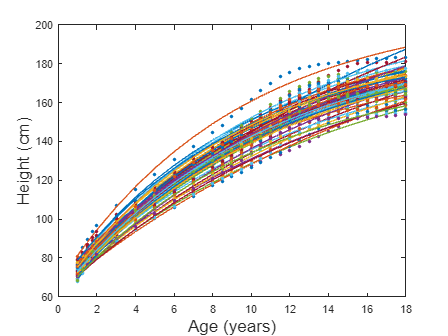

hold off

mae = mean(mae);
mad = mean(mad);
disp(['Mean Absolute Error (MAE) of all the girls: ' num2str(mae), ' cm']);

Mean Absolute Error (MAE) of all the girls: 2.2084 cm


disp(['Median Absolute Deviation (MAD) of all girls: ' num2str(mad), ' cm']);

Median Absolute Deviation (MAD) of all girls: 2.0311 cm


We can represent the evolution of MAE:

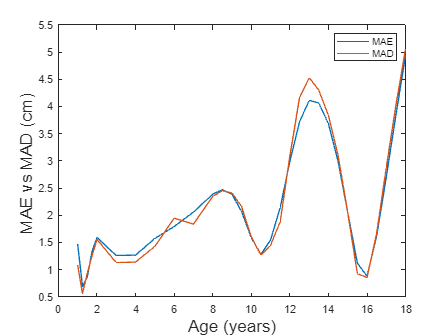

mae_final = mean(mae_2, 2);
mad_final = median(mae_2, 2);
figure
plot (age, mae_final, 'MarkerSize', 20 );
hold on
plot (age, mad_final, 'MarkerSize', 20 );
xlabel('Age (years)','FontSize', 16);

ylabel('MAE vs MAD (cm) ','FontSize', 16);
legend('MAE', 'MAD');

hold off

We calculate the derivatives and represent them

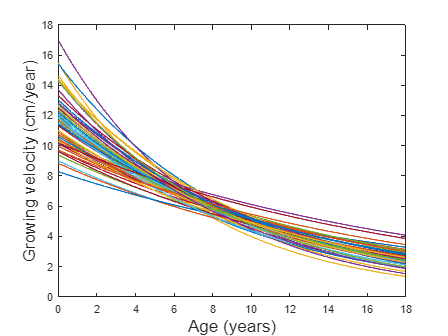

% Defining the derivative of the bertalanffy model
derivative_bertalanffy = @(p, t) p(1) * p(2) * exp(-p(2) * (t - p(3)));
figure();
for girl = 1:54
    adjusted_parameters_girl = adjusted_parameters(girl, :);
    t = 0:0.1:18; % We use t for a more precise reconstruction
    adjusted_model = derivative_bertalanffy(adjusted_parameters_girl, t);
    plot(t, adjusted_model, "-")
    xlabel('Age (years)','FontSize', 16);
    ylabel('Growing velocity (cm/year)','FontSize', 16);
    hold on

end
hold off

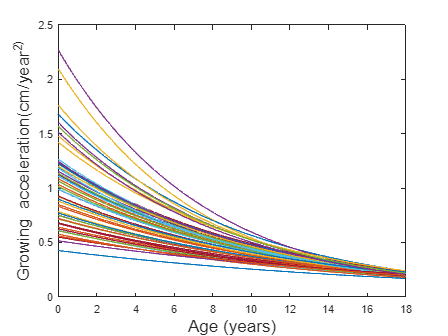

second_derivative_bertalanffy = @(p, t) p(1) * p(2)^2 * exp(-p(2) * (t - p(3)));
figure();
for girl = 1:54
    adjusted_parameters_girl = adjusted_parameters(girl, :);
    t = 0:0.1:18;
    adjusted_model = second_derivative_bertalanffy(adjusted_parameters_girl, t);
    plot(t, adjusted_model, "-")
    xlabel('Age (years)','FontSize', 16);
    ylabel('Growing acceleration(cm/year^2)','FontSize', 16);
    hold on
end
hold off

### 3. JOLICOEUR MODEL

First, we present the ideal parameters proposed by Jolicoeur:

a = 161.7;
e = 0.404;
c = [2.324, 7.514, 11.22];
d = [0.473, 2.946, 15.82];

We define the Jolicoeur model equation and calculate the results for a girl.

jol = @(p, t) p(1) * (1 - 1 ./ ((1 + (t + p(2)) / p(3)).^p(6) + ((t + p(2)) / p(4)).^p(7) + ((t + p(2)) / p(5)).^p(8)));

t = age(:);
h = hgtffit(:, 27);

% Objective function
fun = @(p) sum((jol(p, t) - h).^2);  

% Initial parameters 
p0 = [a e c d];

% Optimization to find the parameters which minimise the function 
p = fminunc(fun, p0);


Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



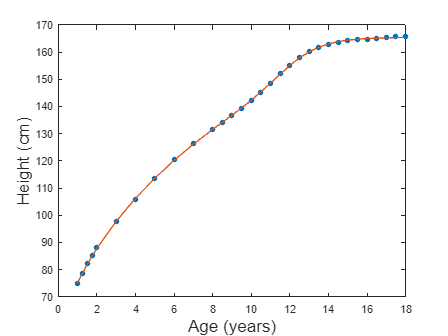


% Plotear los resultados
plot(t, h, '.','MarkerSize', 15);
hold on
plot(t, jol(p, t));
xlabel('Age (years)', 'FontSize', 16); 
ylabel('Height (cm)', 'FontSize', 16); 
hold off

We repeate the process for the whole set


num_girls = size(hgtffit, 2);
p_results = zeros(num_girls, 8);

figure();
mae = zeros(1, 54); 
mad = zeros(1, 54); 
mae_2 = zeros(31,54);

for girl = 1:num_girls
    t = age(:);
    h = hgtffit(:, girl);
    
    % Objective function
    fun = @(p) sum((jol(p, t) - h).^2);  
    
    % Initial parameters (a, e, c, d)
    p0 = [a, e, c, d];
    
    % Optimization to find the parameters which minimize the function 
    p = fminunc(fun, p0);
    
    % Store the parameters in the matrix p_results
    p_results(girl, :) = p;
    
    heights = jol(p, t);

    difference = abs(heights - h);
    mae(girl) = mean(difference);
    mad(girl) = median(difference); 
    
    mae_2(:,girl) = difference;

    % Plotear los resultados
    plot(t, h, '.', 'MarkerSize', 10);
    hold on;
    plot(t, jol(p, t));
    xlabel('Age (years)', 'FontSize', 16); 
    ylabel('Height (cm)', 'FontSize', 16); 
    
end


Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.


Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.


Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.


Solver

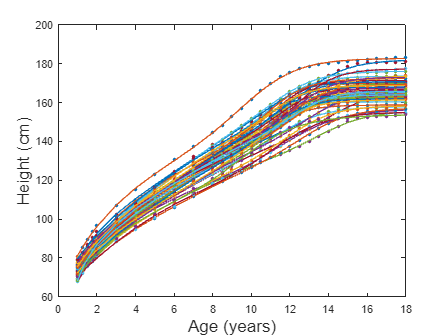

hold off;

We calculate MAE and MAD 

mae = mean(mae);
mad = mean(mad);
disp(['Mean Absolute Error (MAE) of all the girls: ' num2str(mae), ' cm']);

Mean Absolute Error (MAE) of all the girls: 0.22997 cm


disp(['Median Absolute Deviation (MAD) of all girls: ' num2str(mad), ' cm']);

Median Absolute Deviation (MAD) of all girls: 0.19176 cm


We can represent the evolution of MAE:

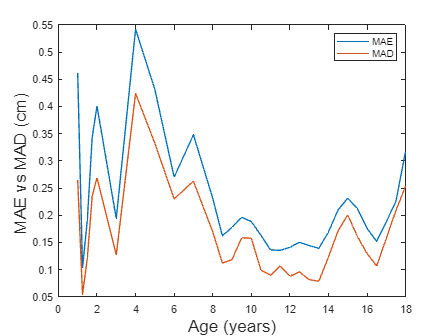

mae_final = mean(mae_2, 2);
mad_final = median(mae_2, 2);
figure
plot (age, mae_final, 'MarkerSize', 20 );
hold on
plot (age, mad_final, 'MarkerSize', 20 );
xlabel('Age (years)','FontSize', 16);

ylabel('MAE vs MAD (cm) ','FontSize', 16);
legend('MAE', 'MAD');

hold off

mae_final = mean (mae);
disp(['Mean Absolute Error (MAE) of all the girls: ', num2str(mae_final), ' cm']);

Mean Absolute Error (MAE) of all the girls: 0.22997 cm


mad_final = mean(mad);
disp(['Median Absolute Deviation (MAD) of all girls: ', num2str(mad_final), ' cm']);

Median Absolute Deviation (MAD) of all girls: 0.19176 cm


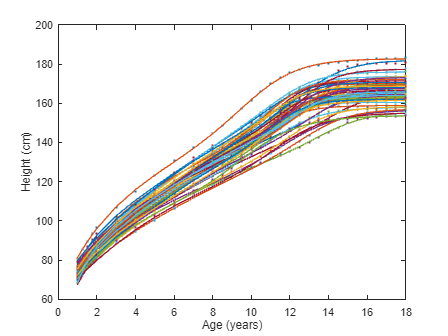


Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.


Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.


Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.


Solver


num_girls = size(hgtffit, 2);
p_results = zeros(num_girls, 8);

heights = zeros(31, num_girls);
first_derivative = zeros(31, num_girls);

figure();
for girl = 1:num_girls
    t = age;
    h = hgtffit(:, girl);
    
    % Objective function
    fun = @(p) sum((jol(p, t) - h).^2);  
    
    % Initial parameters 
    p0 = [a e c d];
    
    % Optimization to find the parameters which minimise the function 
    p = fminunc(fun, p0);
    
    % Store the parameters in the matrix p_results
    p_results(girl, :) = p;
    
    % Obtain the predicted heights for the girl
    heights(:, girl) = jol(p, t);
    
    % We calculate the derivatives and store the results
    first_derivative(:,girl)  = gradient(heights(:, girl), t);
    
    % Plotear los resultados
    
    plot(t, h, '.',t, jol(p, t));
    xlabel('Age (years)');
    ylabel('Height (cm)');
    
hold on

    
    hold on;
end

We have already calculated the derivatives and we can represent them:

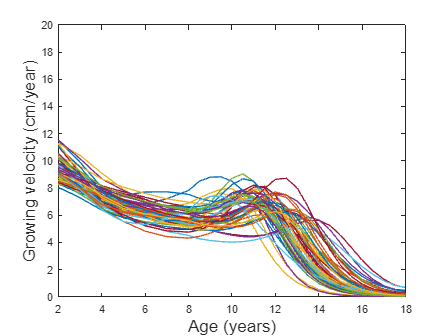

figure();
plot(t, first_derivative, '-');
xlabel('Age (years)','FontSize', 16);
ylabel('Growing velocity (cm/year)','FontSize', 16);
ylim([0 20]);
xlim([2 18])
hold off

### 4. KERNEL SMOOTHING

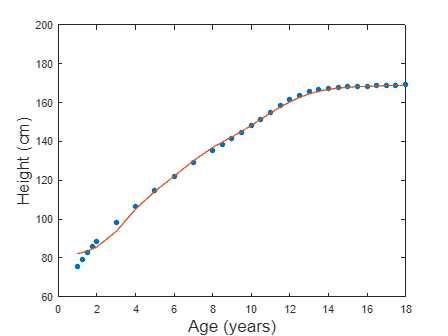



% Bandwidth 
Bw = 1; % We can adjust this value for our needs

% We create a zero vector to store the predicted heights
kernel_smooth_heights = zeros(size(age));

for i = 1:length(age)
    x = age(i);
   
    % Calculate the contribution of each of the observations 
    contributions = kernel_gaussian(age, x, Bw);
    
    % Calculate the predicted heights of the girl
    kernel_smooth_heights(i) = sum(heights .* contributions) / sum(contributions);
end
figure;
plot(age, heights, '.','MarkerSize', 15);
hold on
plot(age, kernel_smooth_heights, '-');
xlabel('Age (years)', 'FontSize', 16); 
ylabel('Height (cm)', 'FontSize', 16); 
ylim([60,200])
hold off

We can replicate the process for the whole data set

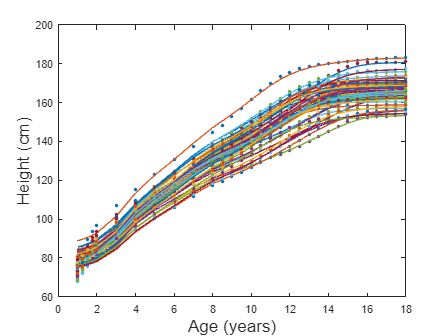

figure();
mae_2 = zeros(31,54);
mae = zeros(1, 54); 
mad = zeros(1, 54); 

all_first_derivatives = [];
all_second_derivatives = [];

for girl = 1:54    
    heights = hgtffit(:,girl);
    kernel_smooth_heights = zeros(size(age));
    for i = 1:length(age)
        x = age(i);
        contributions = kernel_gaussian(age, x, Bw);
        kernel_smooth_heights(i) = sum(heights .* contributions) / sum(contributions);
        diferencia = abs(heights - kernel_smooth_heights);  
        mae_2(:,girl) = diferencia;
        mae(girl) = mean(diferencia);
        mad(girl) = median(diferencia); 
    end
       
    plot(age, heights, '.', 'MarkerSize', 10);
    hold on
    plot(age, kernel_smooth_heights, '-');
    xlabel('Age (years)', 'FontSize', 16); 
    ylabel('Height (cm)', 'FontSize', 16); 

    original_smooth_heights = zeros(size(age));

    % We calculate the predicted heights for each girl
    
    for i = 1:length(age)
        x = age(i);
        contributions = kernel_gaussian(age, x, Bw);
        
        original_smooth_heights(i) = sum(heights .* contributions) / sum(contributions);
    end
    
    hold on
    
end
hold off

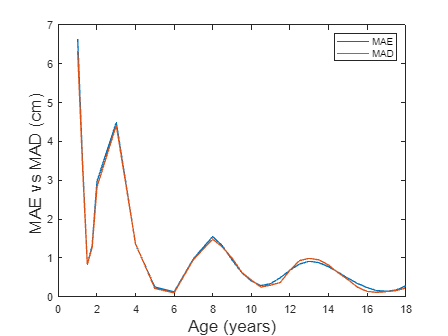

mae_final = mean(mae_2, 2);
mad_final = median(mae_2, 2);
figure
plot (age, mae_final, 'MarkerSize', 20 );
hold on
plot (age, mad_final, 'MarkerSize', 20 );
xlabel('Age (years)','FontSize', 16);

ylabel('MAE vs MAD (cm) ','FontSize', 16);
legend('MAE', 'MAD');

hold off

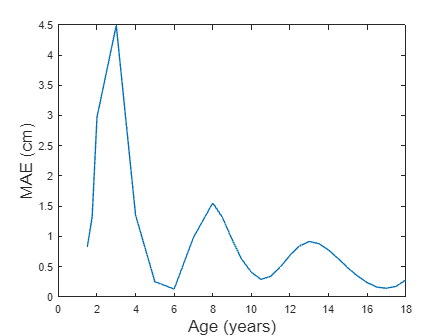

% We repeat the process but eliminating the first 3 values (explained in
% the paper)
mae_2 = mae_2(3:31, :);
mae_2_mean = mean(mae_2, 2);
figure
plot (age(3:31), mae_2_mean,'MarkerSize', 20);
xlabel('Age (years)','FontSize', 16);
ylabel('MAE (cm)','FontSize', 16);
hold off

mae_final = mean (mae);
disp(['Mean Absolute Error of all the girls: ', num2str(mae_final), ' cm']);

Mean Absolute Error of all the girls: 1.1273 cm


mad_final = mean(mad);
disp(['Median Absolute Error of all the girls: ', num2str(mad_final), ' cm']);

Median Absolute Error of all the girls: 0.71311 cm


mae_final_2 = mean (mae_2_mean);
disp(['Mean Absolute Error of all the girls eliminating the first 3 values: ', num2str(mae_final_2), ' cm']);

Mean Absolute Error of all the girls eliminating the first 3 values: 0.85635 cm


We can calculate and represent the derivatives. We use more values in order to have a smoother representation of the derivatives.

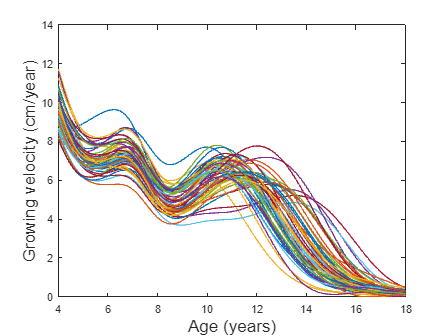

figure(); 

% Create a matrix to store each of the derivatives values
all_first_derivatives = [];
all_second_derivatives = [];

for girl = 1:54    
    edades = age; 
    heights = hgtffit(:, girl);    
    interp_ages = 0:0.1:18; % We increase the number of values to have a better representation
    
    % Inicializa el vector para almacenar las alturas suavizadas
    kernel_smooth_heights = zeros(size(interp_ages));
    
    % Calcular la estimación de densidad de probabilidad para cada punto de edad
    for i = 1:length(interp_ages)
        x = interp_ages(i);
        % Calcular la contribución ponderada de todos los puntos de datos
        contributions = kernel_gaussian(edades, x, Bw);
        
        % Calcular la estimación de densidad en el punto de edad
        kernel_smooth_heights(i) = sum(heights .* contributions);
    end
    
    % We calculate the first derivative and store the values
    kernel_first_derivative = gradient(kernel_smooth_heights, interp_ages);
    kernel_first_derivative(kernel_first_derivative<0) = 0;
    all_first_derivatives = [all_first_derivatives; kernel_first_derivative];
    % We calculate the second derivative and store the values
    kernel_second_derivative = gradient(kernel_first_derivative, interp_ages);
    all_second_derivatives = [all_second_derivatives; kernel_second_derivative];
    
    
end

plot(interp_ages, all_first_derivatives);
xlabel('Age (years)','FontSize', 16);
ylabel('Growing velocity (cm/year)','FontSize', 16);
ylim([0 14])
xlim([4, 18])
hold off;

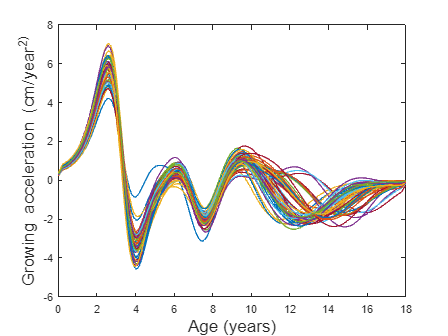

plot(interp_ages, all_second_derivatives);
xlabel('Age (years)','FontSize', 16);
ylabel('Growing acceleration (cm/year^2)','FontSize', 16);
hold off;

### **5.1 SPLINE SMOOTHING CSAPS()**

We start with a single subject

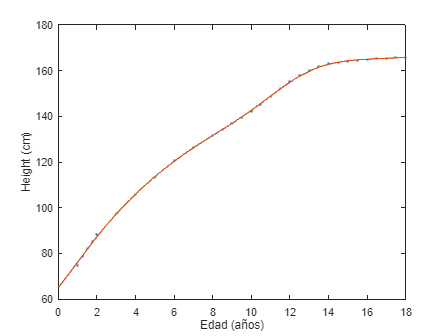

heights = hgtffit(:, 27);
interp_ages = 0:0.1:18;

% Parámetro de suavidad para la penalización de curvatura
smoothingParam = 0.5; % We can adjust this parameter depending on our necessities

% Adjust of a cubic spline using csaps()
spline_result = csaps(age, heights, smoothingParam);

% Evaluation of the spline in the time of observed points
predicted_heights = fnval(spline_result, interp_ages);
predicted_heights = cummax(predicted_heights);    

% Graficar los resultados
plot(age, heights, '.', interp_ages, predicted_heights, '-');
xlabel('Edad (años)');
ylabel('Height (cm)');
hold off

For the representation of the expressions conforming the spline we need to calculate first the number of segments

num_segments = length(spline_result.breaks) - 1;
disp(['Number of segments: ' num2str(num_segments)]);

Number of segments: 30


The number of segments in our case is 30, which coincides with the number of segments we have left if we use the discrete data domain as nodes.

One extra thing we can do to better understand how the spline works is to show the equations of each of these segments:

disp('Equations of the cubic polinomials :');

Equations of the cubic polinomials :


for i = 1:num_segments
    coefficients = spline_result.coefs(i, :);
    fprintf('Segment %d: y(x) = %.4fx^3 + %.4fx^2 + %.4fx + %.4f (para x en [%f, %f])\n', i, coefficients(1), coefficients(2), coefficients(3), coefficients(4), spline_result.breaks(i), spline_result.breaks(i+1));
end

Segment 1: y(x) = -0.2163x^3 + 0.0000x^2 + 11.3173x + 76.2514 (para x en [1.000000, 1.250000])
Segment 2: y(x) = -0.2789x^3 + -0.1622x^2 + 11.2767x + 79.0773 (para x en [1.250000, 1.500000])
Segment 3: y(x) = -0.2394x^3 + -0.3714x^2 + 11.1433x + 81.8820 (para x en [1.500000, 1.750000])
Segment 4: y(x) = -0.1391x^3 + -0.5510x^2 + 10.9127x + 84.6409 (para x en [1.750000, 2.000000])
Segment 5: y(x) = -0.0097x^3 + -0.6553x^2 + 10.6112x + 87.3325 (para x en [2.000000, 3.000000])
Segment 6: y(x) = 0.0593x^3 + -0.6845x^2 + 9.2713x + 97.2786 (para x en [3.000000, 4.000000])
Segment 7: y(x) = 0.0285x^3 + -0.5065x^2 + 8.0804x + 105.9248 (para x en [4.000000, 5.000000])
Segment 8: y(x) = 0.0029x^3 + -0.4211x^2 + 7.1529x + 113.5272 (para x en [5.000000, 6.000000])
Segment 9: y(x) = 0.0350x^3 + -0.4125x^2 + 6.3193x + 120.2619 (para x en [6.000000, 7.000000])
Segment 10: y(x) = 0.0855x^3 + -0.3074x^2 + 5.5994x + 126.2038 (para x en [7.000000, 8.000000])
Segment 11: y(x) = 0.1018x^3 + -0.0511x^2 + 5.

As in the case of MSE Smoothing, there are different regions defined by polynomes. In our case, we have 3 grade polynomes.

As can be seen, we have 30 segments each defined by a cubic function.

To see if our results are optimal we can calculate the mae to compare the original values with the predicted ones.

% Calcular la diferencia entre los datos originales y el spline
predicted_heights = fnval(spline_result, ages);
difference = abs(heights - predicted_heights); % y_interp contiene los valores calculados por el spline


% Calcular el error cuadrático medio (MSE)
mae = mean(difference);

% Mostrar el MSE en la consola
disp(['Mean Absolute Error of a girl using Cubic Splines smoothing: ', num2str(mae)]);

Mean Absolute Error of a girl using Cubic Splines smoothing: 0.29415


For all the girls we have

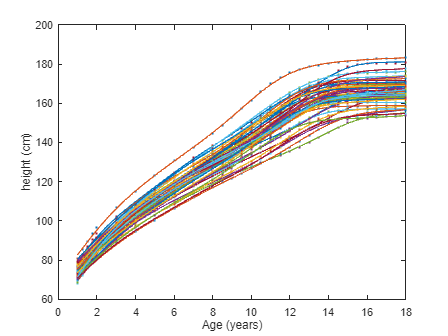

% Plot funciones
figure();
mae = zeros(1, 54); 
mae_2 = zeros(31,54);
mad = zeros(1, 54);
interp_ages = 1:0.1:18;
first_derivative = zeros(171,54);
second_derivative = zeros(171,54);

for girl = 1:54
    ages = age;
    heights = hgtffit(:,girl); 
    smoothingParam = 0.5;
    spline_result = csaps(ages, heights, smoothingParam);
    predicted_heights = fnval(spline_result, interp_ages);
    predicted_heights = cummax(predicted_heights);    
    spline_result = csaps(interp_ages,  predicted_heights, smoothingParam);
    
    plot(ages, heights, '.', interp_ages, predicted_heights, '-');
    xlabel('Age (years)');
    ylabel('height (cm)');
    hold on
    
    total_predicted_heights = fnval(spline_result, ages);
    difference = abs(heights - total_predicted_heights);  
    mae(girl) = mean(difference);
    
    % Añadimos en la matriz los valores de todas las diferencias
    mae_2(:,girl) = difference;
  
    mad(girl) = median(difference); 
    
    % Calcular la primera derivada del spline monótono
    dsp = fnder(spline_result);
    first_derivative(:,girl) = fnval(dsp, interp_ages);
    % Filtrar valores negativos
    first_derivative(first_derivative < 0) = 0;
    
    % Calcular la segunda derivada del spline monótono
    ddsp = fnder(spline_result, 2);
    second_derivative(:,girl) = fnval(ddsp, interp_ages);
    
end
hold off

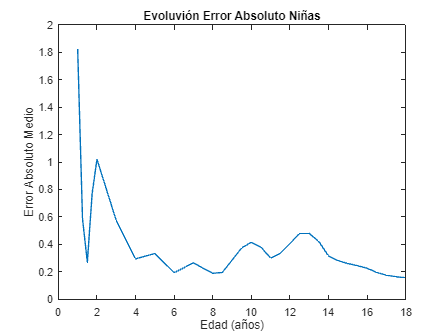

mae_2_mean = mean(mae_2, 2);
figure
plot (age, mae_2_mean);
xlabel('Edad (años)');
ylabel('Error Absoluto Medio');
title('Evoluvión Error Absoluto Niñas');
hold off

mae_final = mean (mae);
disp(['Mean Absolute Error of all the girls: ', num2str(mae_final), ' cm']);

Mean Absolute Error of all the girls: 0.3998 cm


mad_final = mean(mad);
disp(['Median Absolute Error of all the girls: ', num2str(mad_final), ' cm']);

Median Absolute Error of all the girls: 0.30809 cm


We represent the first a second derivative

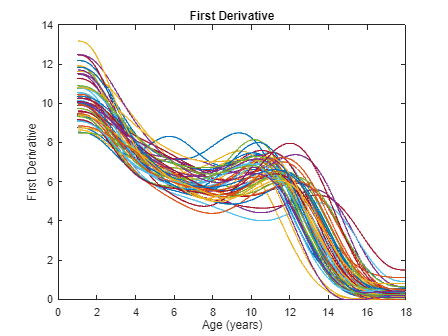

figure();
plot(interp_ages, first_derivative, '-');
title('First Derivative');
xlabel('Age (years)');
ylabel('First Derivative');

hold off

The second derivative is composed by straight lines, thats why I have used in the project the function spaps() instead of csaps() as it allow us to find degree 5 splines, making the second derivative a cubic polinomial.

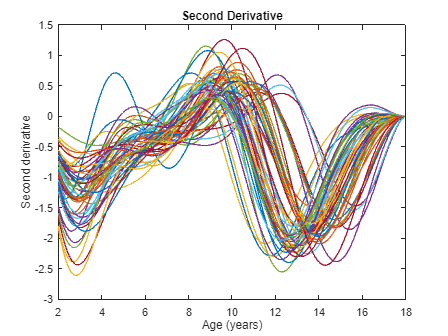

plot(interp_ages, second_derivative, '-');
title('Second Derivative');
xlabel('Age (years)');
ylabel('Second derivative');
xlim([2 18])

hold off

### 5.2.  SPLINE SMOOTHING SPAPS()

Another function that can be used is Spaps(). With this one we can select a polynome of 5 degree, eliminating the problem of linearity in second derivative. For a girl:

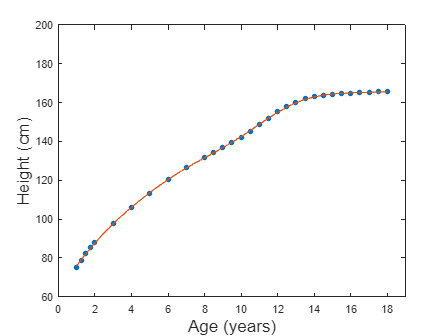

heights = hgtffit(:, 27);
interp_ages = 1:0.1:18;

% Smoothing parameter for the curve penalisation
smoothingParam = 1; % Of course we can adapt this value to our needs

% Ajuste de spline cúbico con penalización de curvatura
spline_result = spaps(age, heights, smoothingParam, [], 3);

% Evaluation of the smooth function in the observed points time.
predicted_heights = fnval(spline_result, interp_ages);
predicted_heights = cummax(predicted_heights);    

figure;
plot(age, heights, '.','MarkerSize', 15);
hold on
plot(interp_ages, predicted_heights, '-');
xlabel('Age (years)','FontSize', 16);
ylabel('Height (cm)','FontSize', 16);
xlim([0 19]);
ylim([60 200]);   

hold off

For all the girls:

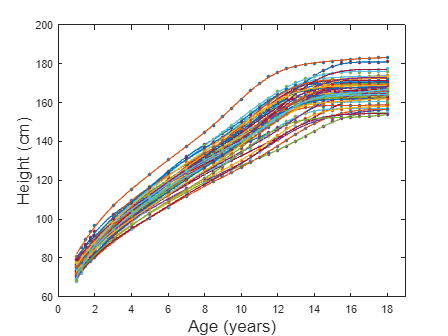

figure();
mae = zeros(1, 54); 
mad = zeros(1, 54); 
mae_2 = zeros(31,54);
first_derivative = zeros(171,54);
second_derivative = zeros(171,54);

for girl = 1:54
    ages = age;
    heights = hgtffit(:, girl); 
    smoothingParam = 1;
    interp_ages = 1:0.1:18;
    
    % Spline smoothing
    spline_result = spaps(ages, heights, smoothingParam, [], 3);
    predicted_heights = fnval(spline_result, interp_ages);
    predicted_heights = cummax(predicted_heights);

    plot(ages, heights, '.','MarkerSize', 10);
    hold on
    plot(interp_ages, predicted_heights, '-');
    xlabel('Age (years)','FontSize', 16);
    ylabel('Height (cm)','FontSize', 16);
    xlim([0 19]);
    hold on
    
    % Calculation of errors
    total_predicted_heights = fnval(spline_result, ages);
    difference = abs(heights - total_predicted_heights);  
    mae(girl) = mean(difference);
    mae_2(:,girl) = difference;
    mad(girl) = median(difference);
    
    % Calculation of derivatives
    dsp = fnder(spline_result); % fnder() allow us to calculate the derivative. Normally used when working with splines.
    first_derivative(:,girl) = fnval(dsp, interp_ages);
    first_derivative(first_derivative < 0) = 0;

    ddsp = fnder(spline_result, 2);
    second_derivative(:,girl) = fnval(ddsp, interp_ages);
    
end

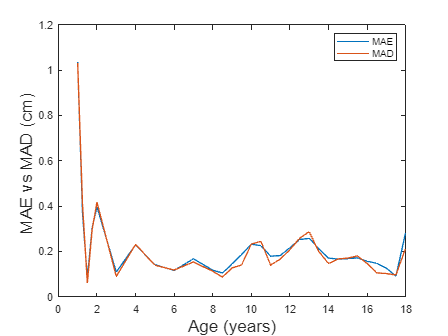

mae_final = mean(mae_2, 2);
mad_final = median(mae_2, 2);
figure
plot (age, mae_final, 'MarkerSize', 20 );
hold on
plot (age, mad_final, 'MarkerSize', 20 );
xlabel('Age (years)','FontSize', 16);

ylabel('MAE vs MAD (cm) ','FontSize', 16);
legend('MAE', 'MAD');

hold off

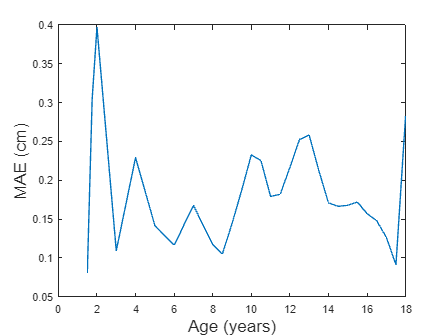

mae_2 = mae_2(3:31, :);
mae_2_mean = mean(mae_2, 2);
figure
plot (age(3:31), mae_2_mean,'MarkerSize', 20);
xlabel('Age (years)','FontSize', 16);
ylabel('MAE (cm)','FontSize', 16);
hold off

mae_final = mean (mae);
disp(['Mean Absolute Error of all the girls: ', num2str(mae_final), ' cm']);

Mean Absolute Error of all the girls: 0.21754 cm


mad_final = mean(mad);
disp(['Median Absolute Error of all the girls: ', num2str(mad_final), ' cm']);

Median Absolute Error of all the girls: 0.16983 cm


mae_final_2 = mean (mae_2_mean);
disp(['Mean Absolute Error of all the girls eliminating the first 4 terms: ', num2str(mae_final_2), ' cm']);

Mean Absolute Error of all the girls eliminating the first 4 terms: 0.18419 cm


1st AND 2nd DERIVATIVE CALCULATION

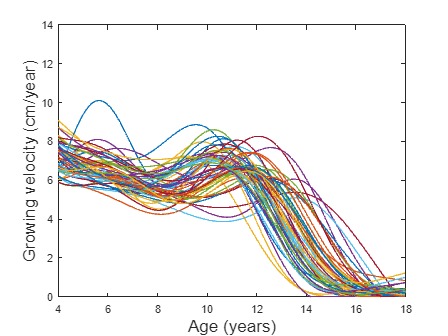

figure();
plot(interp_ages, first_derivative, '-');
xlabel('Age (years)','FontSize', 16);
ylabel('Growing velocity (cm/year)','FontSize', 16);
ylim([0 14]);
xlim([4 18])
hold off

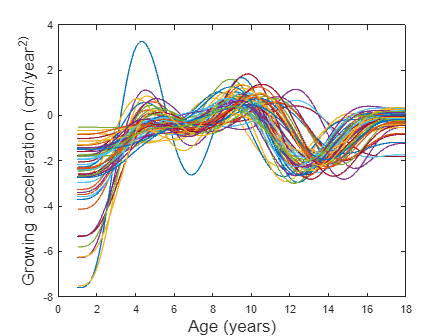

plot(interp_ages, second_derivative, '-');

xlabel('Age (years)','FontSize', 16);
ylabel('Growing acceleration (cm/year^2)','FontSize', 16);


hold off

### GPR SMOOTHING

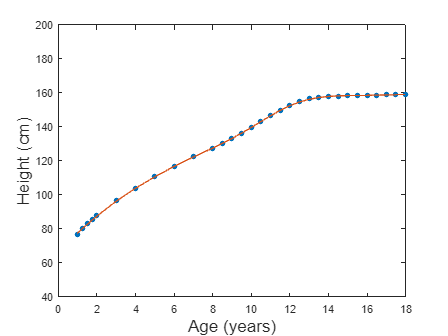

figure();
height = hgtffit(:, 1);

% mean function
sp = csaps(age, hgtffit(:, girl), 1);
mean_fn = @(x) fnval(sp, x);

% autocovariance function
kernel = 'ardmatern32'; % try: ardmatern32, ardmatern52, exponential (malo malo), squaredexponential

% Model
Model = fitrgp(age, height, 'KernelFunction', kernel, ...
    'Beta', 1, 'ConstantSigma', true, 'Sigma', 1);

x = age';
x = x';
[ypred1, ~, ~] = predict(Model, x);


plot(age, height, '.','MarkerSize', 15);
hold on
plot(x, ypred1, '-');    
xlabel('Age (years)','FontSize', 16);
ylabel('Height (cm)','FontSize', 16);
ylim([40, 200])

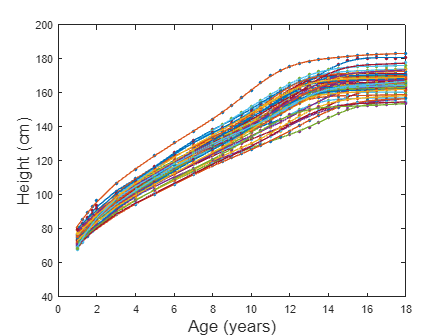


figure();
mae_2 = zeros(31, 54);
mae = zeros(1, 54);
mad = zeros(1, 54);

figure();
for girl = 1:54
    height = hgtffit(:, girl);
    
    % mean function
    sp = csaps(age, hgtffit(:, girl), 1);
    mean_fn = @(x) fnval(sp, x);
    
    % autocovariance function
    kernel = 'ardmatern32'; % try: ardmatern32, ardmatern52, exponential (malo malo), squaredexponential
    
    % Model
    Model = fitrgp(age, height, 'KernelFunction', kernel, ...
        'Beta', 1, 'ConstantSigma', true, 'Sigma', 1);
    
    x = age';
    x = x';
    [ypred1, ~, ~] = predict(Model, x);
    
    % Absolute error
    abs_error = abs(height - ypred1);
    
    % Store Absolute errors
    mae_2(:, girl) = abs_error;
    
    % Calculate and store MAE
    mae(girl) = mean(abs_error);
    
    % Calculate and store MAD
    mad(girl) = median(abs_error);
    
    plot(age, height, '.','MarkerSize', 10);
    hold on
    plot(x, ypred1, '-');    
    xlabel('Age (years)','FontSize', 16);
    ylabel('Height (cm)','FontSize', 16);
    ylim([40, 200])
    hold on
end
hold off

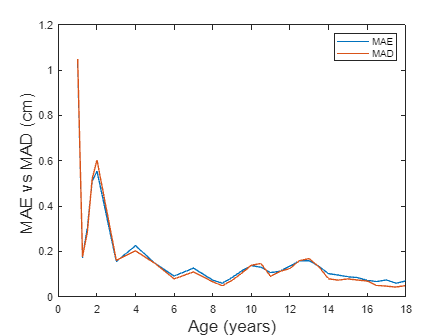

mae_final = mean(mae_2, 2);
mad_final = median(mae_2, 2);
figure
plot (age, mae_final, 'MarkerSize', 20 );
hold on
plot (age, mad_final, 'MarkerSize', 20 );
xlabel('Age (years)','FontSize', 16);

ylabel('MAE vs MAD (cm) ','FontSize', 16);
legend('MAE', 'MAD');

hold off


mae_final = mean (mae);
disp(['Mean Absolute Error of all the girls: ', num2str(mae_final), ' cm']);

Mean Absolute Error of all the girls: 0.17573 cm


mad_final = mean(mad);
disp(['Median Absolute Error of all the girls: ', num2str(mad_final), ' cm']);

Median Absolute Error of all the girls: 0.11734 cm


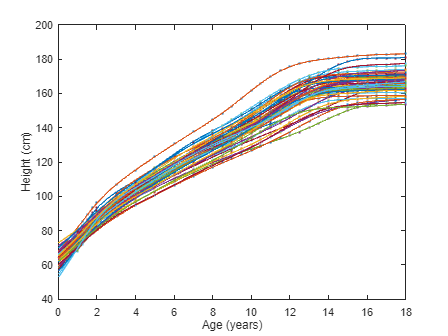

num_girls = size(hgtffit, 2);
figure();
mae_2 = zeros(31, 54);
mae = zeros(1, 54);
mad = zeros(1, 54);
heights = zeros(361, num_girls);
first_derivative = zeros(361, num_girls);
second_derivative = zeros(361, num_girls);

figure();
for girl = 1:54
    height = hgtffit(:, girl);
    
    % mean function
    sp = csaps(age, hgtffit(:, girl), 1);
    mean_fn = @(x) fnval(sp, x);
    
    % autocovariance function
    kernel = 'ardmatern32'; % try: ardmatern32, ardmatern52, exponential (malo malo), squaredexponential
    
    % Model
    Model = fitrgp(age, height, 'KernelFunction', kernel, ...
        'Beta', 1, 'ConstantSigma', true, 'Sigma', 1);
    
    x = 0:0.05:18;
    x = x';
    [ypred1, ~, ~] = predict(Model, x);
    
     % Obtain the predicted heights for the girl
    heights(:, girl) = ypred1;
    
    % We calculate the derivatives and store the results
    first_derivative(:,girl)  = gradient(heights(:, girl), x);
    second_derivative(:,girl) = gradient(first_derivative(:,girl), x);
   
    
    plot(age, height, '.', x, ypred1, '-')    
    xlabel('Age (years)');
    ylabel('Height (cm)');
    ylim([40, 200])
    hold on
end
hold off

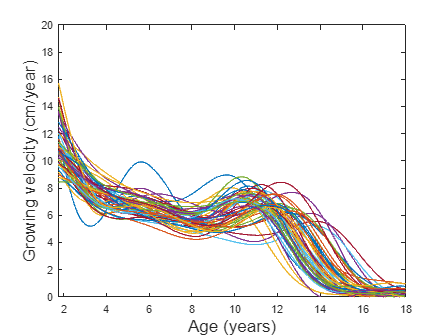

figure();
plot(x, first_derivative, '-');
xlabel('Age (years)','FontSize', 16);
ylabel('Growing velocity (cm/year)','FontSize', 16);
ylim([0 20]);
xlim([1.75 18])
hold off

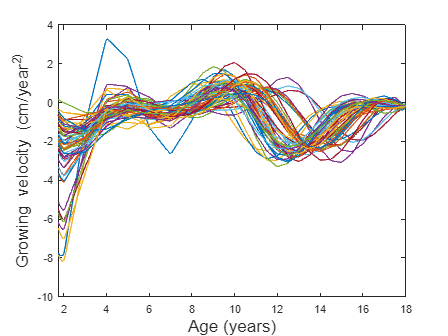

figure();
plot(x, second_derivative, '-');
xlabel('Age (years)','FontSize', 16);
ylabel('Growing velocity (cm/year^2)','FontSize', 16);
xlim([1.75, 18])
hold off

GPR (PREDICTION)

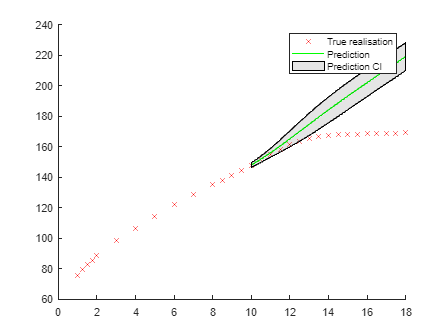


age_limit=10;
k=find(age>age_limit,1)-1;

% mean function
sp = csaps(age(1:k), height(1:k), 0.5);
mean= @(x) fnval(sp,x);  %try: none, linear

% autocovariance function
kernel='squaredexponential'; % try: ardmatern32,ardmatern52, exponential, squaredexponential
% 'KernelFunction','ardmatern32' Squared exponential kernel
%Model=fitrgp(edad,altura); % Squared Exponential Kernel

Model=fitrgp(age(1:k),height(1:k),'KernelFunction',kernel,'BasisFunction','linear',...
    'Beta',[1 1],'ConstantSigma',true,'Sigma',0.6); 

% Plots
figure();
x = age(k):.05:18; x=x';
[ypred1,~,yint1] = predict(Model,x);
%[ypred2,~,yint2] = predict(Model,x);

hold on
scatter(age,height,'xr') % Observed data points

plot(x,ypred1,'g')    
patch([x;flipud(x)],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
legend('True realisation','Prediction','Prediction CI')

### MONOTONY TEST

I have tried to treat the data before making the smothing method. The idea under this is to make it easier to have positive values in the first derivative (monotonic) without doing artificial limitations..,64-<

56.

- Calculate the gradient of the initial data gradient(data)

- Transform the gradient with exp(gradient)

- Apply the spline on this data

- Undo the transformation with log(data_spline)

#### 1 Calculate the gradient of the initial data gradient(data)

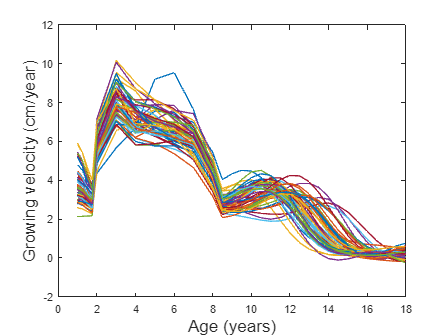

figure();
load('AlturaChicas.mat')
load('EdadChicas.mat')
gradient_data_matrix = zeros(length(age), 54);

for girl = 1:54
    gradient_data = gradient(hgtffit(:, girl));
    plot(age, gradient_data)
    ylim([-2, 12]);
    xlabel('Age (years)','FontSize', 16);
    ylabel('Growing velocity (cm/year)','FontSize', 16);
    hold on

    % Store the values of the gradient in the matrix
    gradient_data_matrix(:, girl) = gradient_data;
end

hold off

#### 2 Transform the gradient with exp(gradient)

exp_gradient_data_matrix = exp(gradient_data_matrix);

#### 3 Apply the spline on this data

figure();

spline_result_matrix = zeros(length(interp_ages), 54);
smoothingParam = 0.1;
interp_ages = 1:0.1:18;

for girl = 1:54
    ages = age;
    heights = exp_gradient_data_matrix(:, girl);
    
    % Realiza el suavizado de splines
    spline_result = spaps(ages, heights, smoothingParam, [], 3);
    
    % Calcula los valores predichos por el spline
    predicted_heights = fnval(spline_result, interp_ages);
    
    % Almacena los valores de spline_result en la matriz
    spline_result_matrix(:, girl) = predicted_heights;
end

hold off

#### 4

monotone_spline = log(spline_result_matrix);
plot (interp_ages, monotone_spline)

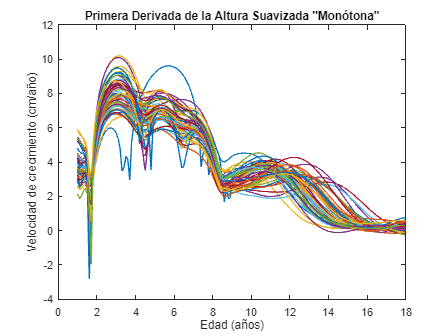

xlabel('Edad (años)');
ylabel('Velocidad de crecimiento (cm/año)');
title('Primera Derivada de la Altura Suavizada "Monótona"');

## Depth analysis and confidence interval creation

We are going to use an interval of 0.25 years (explained in the paper).

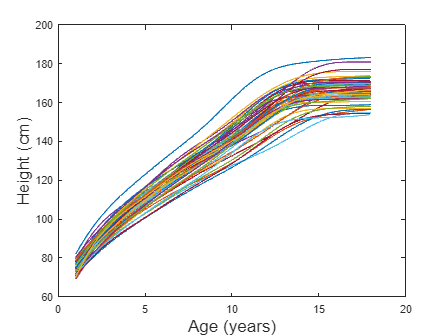

ages_interp = 1:0.05:18; % We establish a step of 0.05 years which allow us to construct different studies

figure();

predicted_girl_height_mat = zeros(length(ages_interp), 54); % Matrix to store predicted heights

for girl = 1:54
    heights_girl = hgtffit(:, girl);
    smoothingParam = 1;
 
    
    % Spline smoothing
    spline_result = spaps(age, heights_girl, smoothingParam,[], 3);
    predicted_heights = fnval(spline_result, ages_interp);
    predicted_heights = cummax(predicted_heights);
    
    predicted_girl_height_mat(:, girl) = predicted_heights; 
    
    plot(ages_interp, predicted_heights, '-');
    xlabel('Age (years)','FontSize', 16);
    ylabel('Height (cm)','FontSize', 16);
    xlim([0 20]);
    hold on
end

Now we select 1 of each 5 values in order to have a separation of 0.25 years.

predicted_girl_height_mat = predicted_girl_height_mat(1:5:end, :);
ages_interp = ages_interp(1:5:end);

Una vez tenemos los datos preparados vamos a proceder con el cálculo de la profundidad. La idea es sencilla y vamos a separarlo en 2 partes en función de las curvas que usemos como límites:

### Construcción de límite con 2 curvas

La idea es coger todos los pares de curvas posibles y tratarlos como un límite del rango donde han de estar contenidas el resto de curvas. Es decir, vamos a coger por ejemplo la curva 1 y 2, y analizar si el resto de curvas pasan o no entre estas dos. En el caso de que una de ellas esté plenamente contenida, sumaremos 1 a su marcador. La idea es que al final del estudio, las curvas con mayor puntuación serán más profundas. 

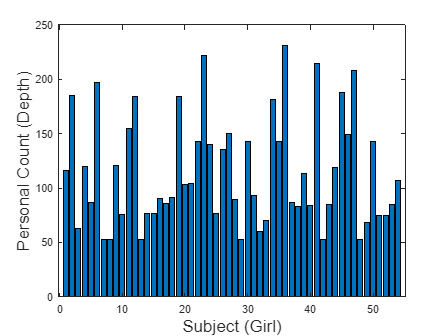

[n_ages, n_girls] = size(predicted_girl_height_mat);
personal_count = zeros (54, 1);
C = nchoosek(1:54, 2);
b = nchoosek (54, 2);

% Loop to find the possible groups formed by 2 curves from the set
for i = 1:b
    girl1 = C(i, 1);
    girl2 = C(i, 2);
    
    superior_limit = max([predicted_girl_height_mat(:, girl1),predicted_girl_height_mat(:, girl2)], [], 2);
    inferior_limit = min([predicted_girl_height_mat(:, girl1),predicted_girl_height_mat(:, girl2)], [], 2);

    % Loop to study the rest of the curves with respect to the limit
    for girl3 = 1:n_girls
        if girl3 == girl1 || girl3 == girl2 
            personal_count(girl3) = personal_count(girl3) + 1;
        else
             % Verify if the curve is within the limits
            content = all(predicted_girl_height_mat(:, girl3) >= inferior_limit & predicted_girl_height_mat(:, girl3) <= superior_limit);
            % Increment personal_account if contained, that is, if contained is True
            if content
            personal_count(girl3) = personal_count(girl3) + 1;
            end
        end

    end
end

% personal_count contains the individual score of how many times each curve is contained between three other curves.
% The curve with the highest personal account will have the greatest depth.


personal_count_2_curves = personal_count; 
figure;
bar(personal_count_2_curves);
xlabel('Subject (Girl)','FontSize', 16);
ylabel('Personal Count (Depth)','FontSize', 16);

nchoosek(54, 2) % If the curve is contained between all pairs, this value would be the personal count.

ans = 1431

We repeate the process but adding an extra curve to the limit in order to avoid intersection in pairs.

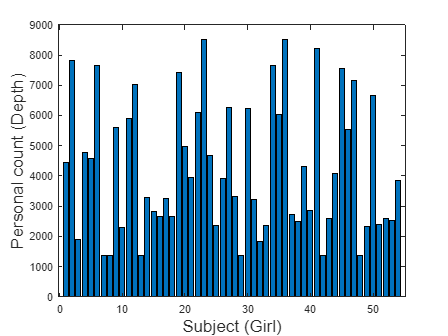

personal_count = zeros (54, 1);
C = nchoosek(1:54, 3);
c = nchoosek (54, 3);

[n_ages, n_girls] = size(predicted_girl_height_mat);

% Loop to find the possible groups formed by 3 curves from the set
for i = 1:c
    girl1 = C(i, 1);
    girl2 = C(i, 2);
    girl3 = C(i, 3);
    
    superior_limit = max([predicted_girl_height_mat(:, girl1),predicted_girl_height_mat(:, girl2), predicted_girl_height_mat(:, girl3)], [], 2);
    inferior_limit = min([predicted_girl_height_mat(:, girl1),predicted_girl_height_mat(:, girl2), predicted_girl_height_mat(:, girl3)], [], 2);

    % Loop to study the rest of the curves with respect to the limit
    for girl4 = 1:n_girls
        if girl4 == girl1 || girl4 == girl2 || girl4 == girl3 
            personal_count(girl4) = personal_count(girl4) + 1;
        else

            % Verify if the curve is within the limits
            content = all(predicted_girl_height_mat(:, girl4) >= inferior_limit & predicted_girl_height_mat(:, girl4) <= superior_limit);
    
            % Increment personal_account if contained, that is, if contained is True
            if content
                personal_count(girl4) = personal_count(girl4) + 1;
            end
        end
    end
end


figure;
bar(personal_count);
xlabel('Subject (Girl)','FontSize', 16);
ylabel('Personal count (Depth)','FontSize', 16);

nchoosek(54, 3) % If the curve is contained between all pairs, this value would be the personal count.

ans = 24804

The normalization of the data is usually done when working with different scales, it allow us to have a clearer representation.

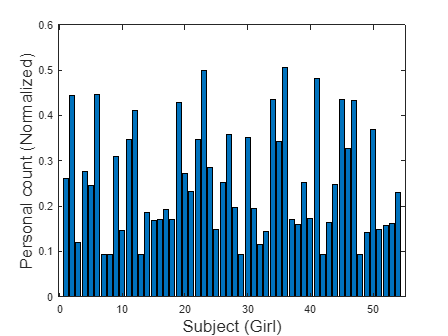


personal_count_2_curves = personal_count_2_curves / b; % Para 2 curvas como límites
personal_count = personal_count / c; % Para 3 curvas como límites
personal_count = personal_count + personal_count_2_curves;


figure;
bar(personal_count);
xlabel('Subject (Girl)','FontSize', 16);
ylabel('Personal count (Normalized)','FontSize', 16);

We can represent the most depth curves and the ones that are the most atypical ones. For that, we only need to see which curves have higher (depth) and the lowest (atypical) values on the previous graph.

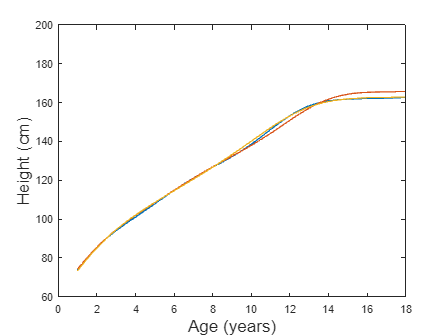

figure();
plot(ages_interp, predicted_girl_height_mat(:, [23,36,41]));
hold off
xlabel('Age (years)','FontSize', 16);
ylabel('Height (cm)','FontSize', 16);
ylim([60 200])

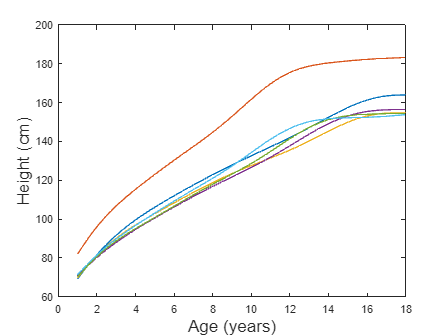

figure();
plot(ages_interp, predicted_girl_height_mat(:, [7, 8, 13, 29, 42, 48]));
xlabel('Age (years)','FontSize', 16);
ylabel('Height (cm)','FontSize', 16);
ylim([60 200])
hold off

Confidence range calculation

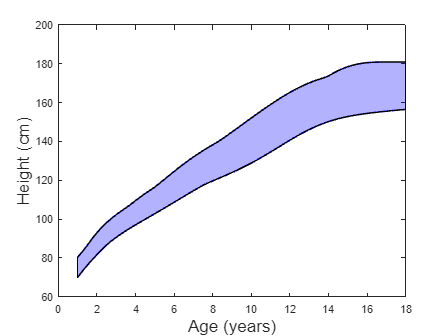

personal_count = personal_count + personal_count_2_curves;

% We order the curves according to the depth measurement (normalised personal_count).
[~, ordered_indexes] = sort(personal_count, 'descend');

% Select the 43 deepest curves (80 %). We can change the value to increase
% or decrease the range.

deepests_curves = ordered_indexes(1:43); 

% Initialize arrays to store the maximum and minimum values ��at each time
% point.
max_values = zeros(length(ages_interp), 1);
min_values = zeros(length(ages_interp), 1);

% Iterate over the selected curves to calculate the maximum and minimum
% values at each time point.
for i = 1:length(ages_interp)
    values = predicted_girl_height_mat(i, deepests_curves);
    max_values(i) = max(values);
    min_values(i) = min(values);
end


% Plot del rango de confianza
figure;

% Plot de las curvas difuminadas
plot(ages_interp, max_values, 'b-', 'LineWidth', 1.5, 'Color', [0, 0, 1, 0.3]); % Difuminar curva superior
hold on;
plot(ages_interp, min_values, 'b-', 'LineWidth', 1.5, 'Color', [0, 0, 1, 0.3]); % Difuminar curva inferior

% Rellenar la banda de color
fill([ages_interp.'; flipud(ages_interp.')], [max_values; flipud(min_values)], 'blue', 'FaceAlpha', 0.3);



xlabel('Age (years)','FontSize', 16);
ylabel('Height (cm)','FontSize', 16);
ylim([60, 200])
hold off

# Wilcoxon rank-sum test

We calculate the values that are going to be used during the test (each 0.25 years) 

For boys:

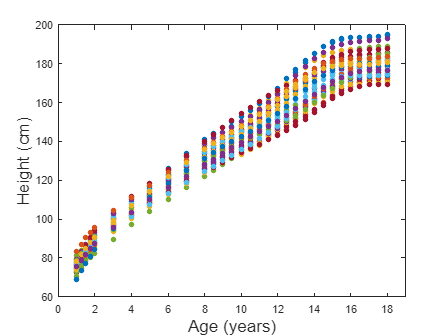

figure();
for girl = 1:39
    individual_heights = hgtmfit(:,girl);
    plot(age, individual_heights, '.', 'MarkerSize', 15); % Representation of the data
    hold on; 
end
xlabel('Age (years)', 'FontSize', 16); 
ylabel('Height (cm)', 'FontSize', 16); 
xlim([0, 19]);
ylim([60, 200]);
hold off

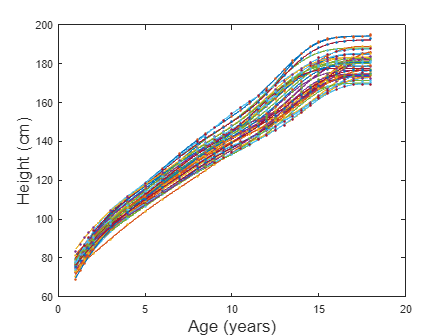

ages_interp = 1:0.05:18; 

figure();

predicted_boys_height_mat = zeros(length(ages_interp), 39); % Matriz para almacenar las alturas predichas

alturas = hgtmfit;

for man = 1:39
    edades_man = age;
    alturas_man = alturas(:, man);
    smoothingParam = 1;
 
    
    % Realiza el suavizado de splines
    spline_result = spaps(edades_man, alturas_man, smoothingParam, [], 3);
    predicted_heights = fnval(spline_result, ages_interp);
    predicted_heights = cummax(predicted_heights);
    
    predicted_boys_height_mat(:, man) = predicted_heights; % Almacena las alturas predichas en la matriz
    
    % Grafica los datos y la curva suavizada
    plot(ages_interp, predicted_heights, '-', ages, hgtmfit(:,man), '.','MarkerSize', 7);
    xlabel('Age (years)','FontSize', 16);
    ylabel('Height (cm)','FontSize', 16);
    xlim([0 20]);
    hold on
end


predicted_boys_height_mat = predicted_boys_height_mat(1:5:end, :);
ages_interp = ages_interp(1:5:end);


boys_smooth = predicted_boys_height_mat;
girls_smooth = predicted_girl_height_mat;

max_age = 14; % Maximum age at which you want to take the test; changing this
% number you can do the test up to different ages to see if at any point
% moment we go from having no evidence to reject the hypothesis to
% accept it

age_test = 1:0.25:18;
pos = find(age_test<=max_age, 1, 'last' );

boys = boys_smooth(1:pos,:);
girls = girls_smooth(1:pos,:);

n_boys=length(boys_smooth(1,:));
n_girls=length(girls_smooth(1,:));

nz=30; nx=n_girls-nz; ny=n_boys;

seed= 30; 
rng(seed) 
sample = randsample(1:n_girls,nz);

ind_x=setdiff(1:n_girls,sample);

Z = girls(:,sample); % Z sampple
X = girls(:,ind_x); % 
Y = boys;

We can apply the depth test. For 2 limiting curves:

C = nchoosek(1:nz, 2);
b = nchoosek (nz, 2);

counter_x=zeros(nx,1);
counter_y=zeros(ny,1);

% Loop to find all the possibilities of forming the group of 2 curves
for i = 1:b
    z1 = C(i, 1);
    z2 = C(i, 2);
    
    limit_superior = max([Z(:, z1),Z(:, z2)], [], 2);
    limit_inferior = min([Z(:, z1),Z(:, z2)], [], 2);

    % Loop to compare each group with the rest of the girls
    for x = 1:nx
        % Verify if the curve is inside the limits
        content = all(X(:, x) >= limit_inferior & X(:, x) <= limit_superior);
        % Increment the value "content" if it is TRUE
        if content
            counter_x(x) = counter_x(x) + 1;
        end
    end
    
    % Loop to compare each group with the boys
    for y = 1:ny
        content = all(Y(:, y) >= limit_inferior & Y(:, y) <= limit_superior);
        if content
            counter_y(y) = counter_y(y) + 1;
        end
    end
end

BDx_2=counter_x/b;
BDy_2=counter_y/b;

And 3:

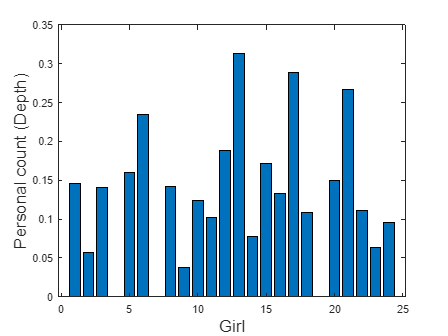

D = nchoosek(1:nz, 3);
d = nchoosek (nz, 3);

counter_x=zeros(nx,1);
counter_y=zeros(ny,1);

% Loop to find all the possibilities fro forming the group of 3 curves
for i = 1:d
    z1 = D(i, 1);
    z2 = D(i, 2);
    z3 = D(i, 3);
    
    limit_superior = max([Z(:, z1),Z(:, z2)], [], 2);
    limit_inferior = min([Z(:, z1),Z(:, z2)], [], 2);

    % Loop to compare each group with the rest of the girls
    for x = 1:nx
        % Verify if the curve is inside the limits
        content = all(X(:, x) >= limit_inferior & X(:, x) <= limit_superior);

        % Increment the value "content" if it is TRUE
        if content
            counter_x(x) = counter_x(x) + 1;
        end
    end
    % Loop to compare each group with the boys
    for y = 1:ny
        content = all(Y(:, y) >= limit_inferior & Y(:, y) <= limit_superior);
        
        if content
            counter_y(y) = counter_y(y) + 1;
        end
    end
end



BDx_3=counter_x/d;
BDy_3=counter_y/d;

% We sum both studies
BDx = BDx_2 + BDx_3; 
BDy = BDy_2 + BDy_3; 

figure;
bar(BDx);
xlabel('Girl','FontSize', 16);
ylabel('Personal count (Depth)','FontSize', 16);

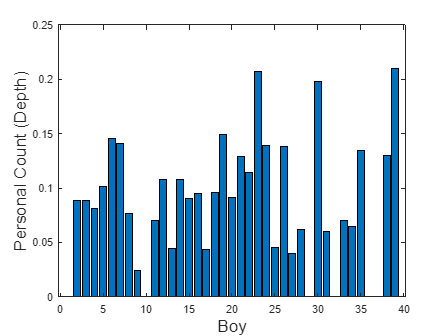


figure;
bar(BDy);
xlabel('Boy','FontSize', 16);
ylabel('Personal Count (Depth)','FontSize', 16);

And we finally do the test:

% We add both vectors
BD = [BDx; BDy];

% Order from lowest to highest and return the indexes
[BD_sorted, order] = sort(BD');

% rank assignment
ranks = 1:length(BD);

% Recovering the original sets with the rank assignment
BDx_ranks = ranks(order <= length(BDx));
BDy_ranks = ranks(order > length(BDx));

% Computing the test
alpha=0.05;
[p,h] = ranksum(BDx_ranks,BDy_ranks) % BDx and BDy are de samples with the ranks of each population.

p = 0.0483

h = logical
   1


if p<=alpha
    disp("Null hypothesis is rejected")
else
    disp("There is not enough evidence to reject the null hypothesis.")
end

Null hypothesis is rejected


function contributions = kernel_gaussian(ages, x, h)
    kernel = exp(-((ages - x).^2) / (2 * h^2)) / (sqrt(2 * pi) * h);
    
    % Normalization of the kernel
    kernel = kernel / sum(kernel);
    
    % Return the contributions
    contributions = kernel;
end
